# 创建深度学习网络架构

该脚本可创建具有以下属性的深度学习网络:

运行脚本以在工作区变量 `lgraph` 中创建层。

要了解详细信息，请参阅 [从深度网络设计器生成 MATLAB 代码](matlab:helpview('deeplearning','generate_matlab_code'))。

由 MATLAB 于 2022-10-24 17:17:38 自动生成

## 创建层次图

创建层次图变量以包含网络层。

lgraph = layerGraph();

## 添加层分支

将网络分支添加到层次图中。每个分支均为一个线性层组。

tempLayers = [
    imageInputLayer([4 125 1],"Name","imageinput4")
    convolution2dLayer([4 4],16,"Name","conv4","Padding","same","Stride",[4 1])
    reluLayer("Name","relu_3")
    flattenLayer("Name","flatten4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    imageInputLayer([4 500 1],"Name","imageinput1")
    convolution2dLayer([4 4],2,"Name","conv1","Padding","same","Stride",[32 1])
    reluLayer("Name","relu_4")
    flattenLayer("Name","flatten1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    imageInputLayer([4 125 1],"Name","imageinput3")
    convolution2dLayer([4 4],8,"Name","conv3","Padding","same","Stride",[8 1])
    reluLayer("Name","relu_2")
    flattenLayer("Name","flatten3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    imageInputLayer([4 250 1],"Name","imageinput2")
    convolution2dLayer([4 4],4,"Name","conv2","Padding","same","Stride",[16 1])
    reluLayer("Name","relu_1")
    flattenLayer("Name","flatten2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    concatenationLayer(1,4,"Name","concat")
    fullyConnectedLayer(3,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% 清理辅助变量
clear tempLayers;

## 连接层分支

连接网络的所有分支以创建网络图。

lgraph = connectLayers(lgraph,"flatten4","concat/in4");
lgraph = connectLayers(lgraph,"flatten3","concat/in3");
lgraph = connectLayers(lgraph,"flatten1","concat/in1");
lgraph = connectLayers(lgraph,"flatten2","concat/in2");

## 绘制层

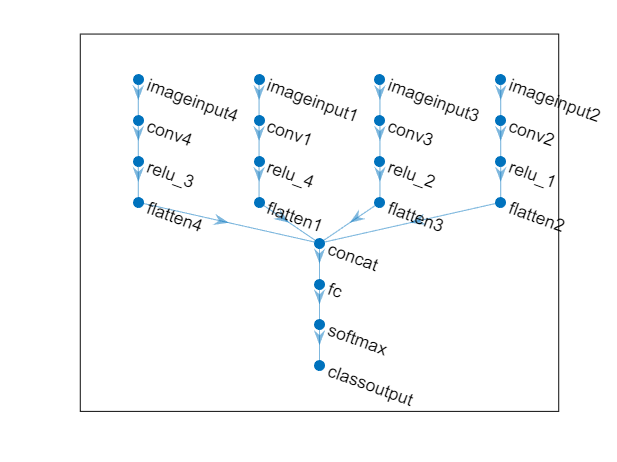

plot(lgraph);